Q1

gamma

i = imread ("CLOWN_LUMI.BMP.BMP")

i = 194×259×3 uint8 array
i(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   251   249   249   249   251   251   251   251   252   252   254   254   255   255   255   254   254   252   252   252   252   252   252   252   252   252   252   252   252   252   252   254   255   255   255   255   255   255   255   255   254   254   252   252   252   252   251   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252  

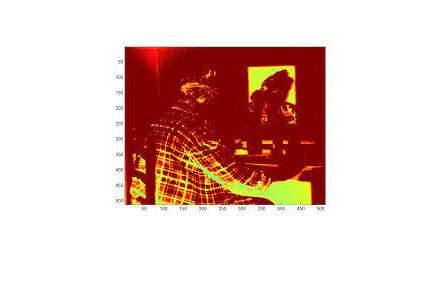

imshow(i)


r = 0:1/255:1;
g = 0:1/255:1;
b = 0:1/255:1;
map = [r' g' b'] % transpose = '

map =          0         0         0
    0.0039    0.0039    0.0039
    0.0078    0.0078    0.0078
    0.0118    0.0118    0.0118
    0.0157    0.0157    0.0157
    0.0196    0.0196    0.0196
    0.0235    0.0235    0.0235
    0.0275    0.0275    0.0275
    0.0314    0.0314    0.0314
    0.0353    0.0353    0.0353


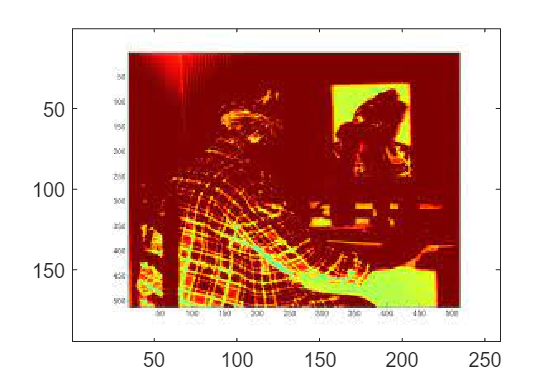

image(i)
colormap(map) %enhances red,green,blue

gray_i = im2gray(i) % or rgb2gray(i)

gray_i = 194×259 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   253   253   253   254   254   254   254   254   254   255   255   255   255   255   255   255   254
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   254   254   254   254   254   254   255   255   255   255   255   255   255   255   254   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   254   254   254   254   254
   255   255   255   255   255   255   255   255   255   255   255 

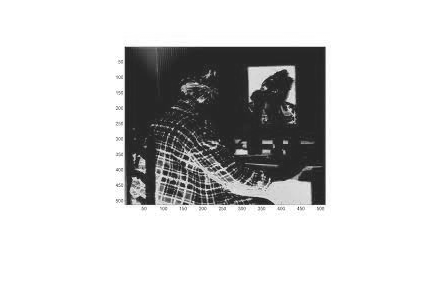


imshow(gray_i)



vect = 0:1/255:1;
gam_r = 2.1;
gam_g = 2.2;
gam_b = 2.3;

r = vect.^(1/gam_r);
g = vect.^(1/gam_g);
b = vect.^(1/gam_b);
gamma_map = [r' g' b']

gamma_map =          0         0         0
    0.0715    0.0806    0.0899
    0.0994    0.1104    0.1215
    0.1206    0.1327    0.1449
    0.1383    0.1513    0.1642
    0.1538    0.1674    0.1810
    0.1677    0.1819    0.1959
    0.1805    0.1951    0.2095
    0.1923    0.2073    0.2220
    0.2034    0.2187    0.2337


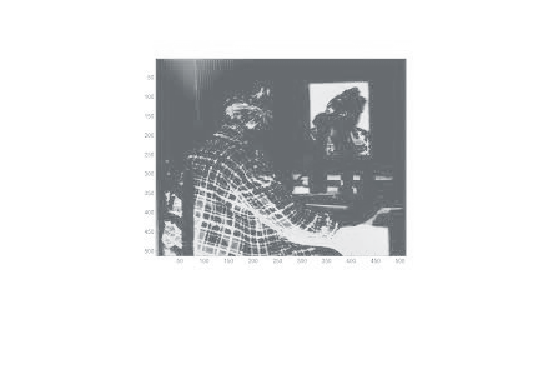

colormap(gamma_map)

Q2

close all 
clear all

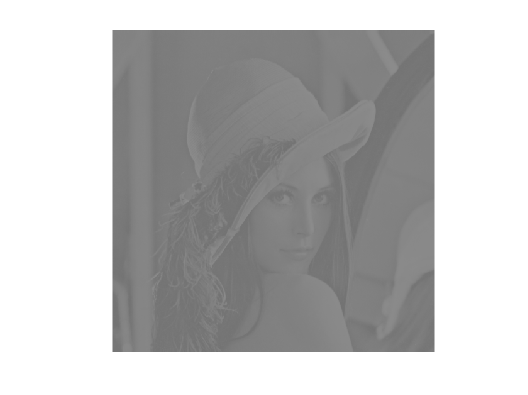

I = imread('Lenna2.png');
pippo = rgb2gray(I);

imshow(pippo)

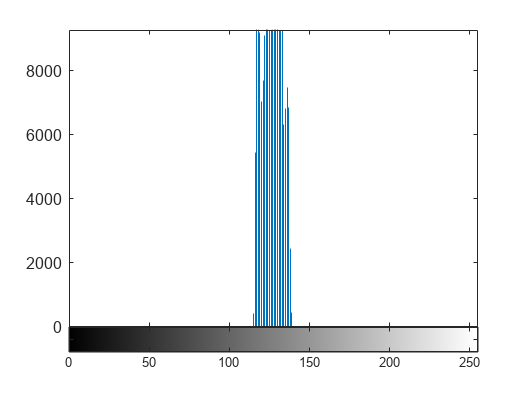

figure
imhist(pippo)

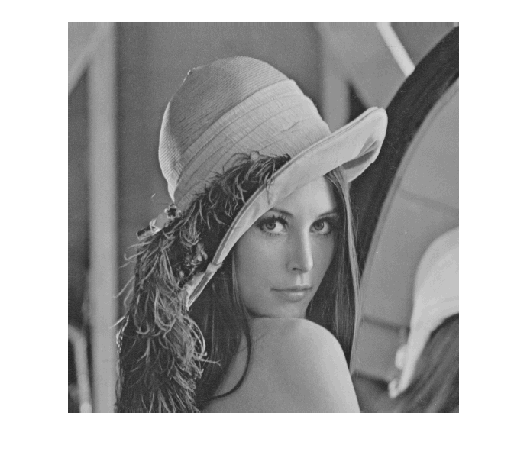


e =contraststretching(pippo,110/255,0.01,145/255,0.99);

figure
imshow(e)

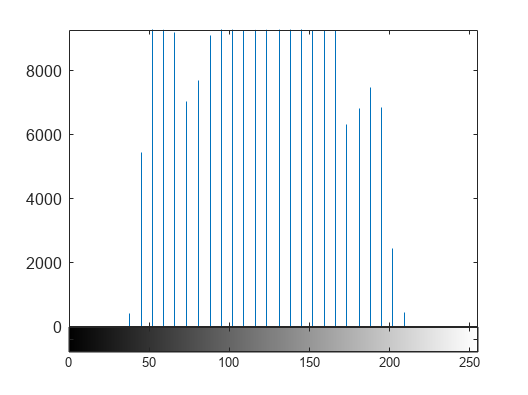

figure
imhist(e)

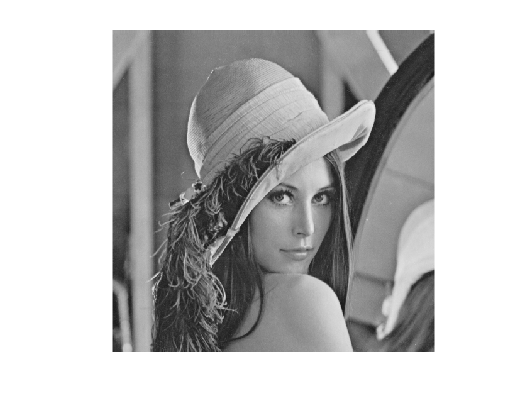

It = imread('Lenna.png');
pippo2 = rgb2gray(It);

imshow(pippo2)

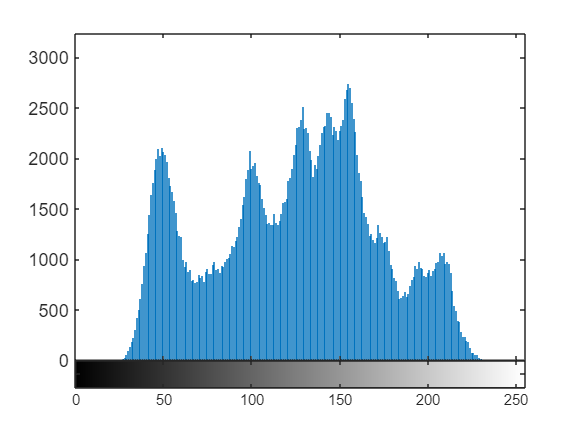

figure
imhist(pippo2)

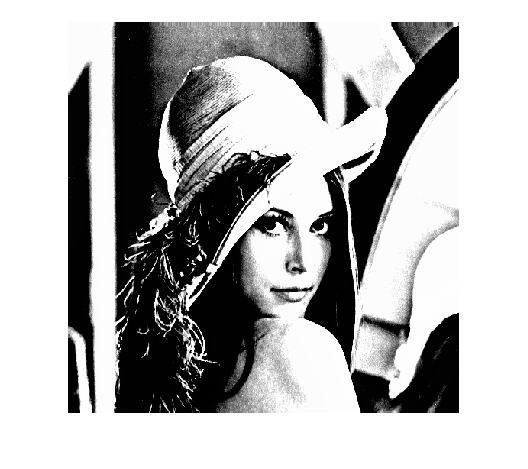


f =contraststretching2(pippo2,110/255,0.01,145/255,0.99);

figure
imshow(f)

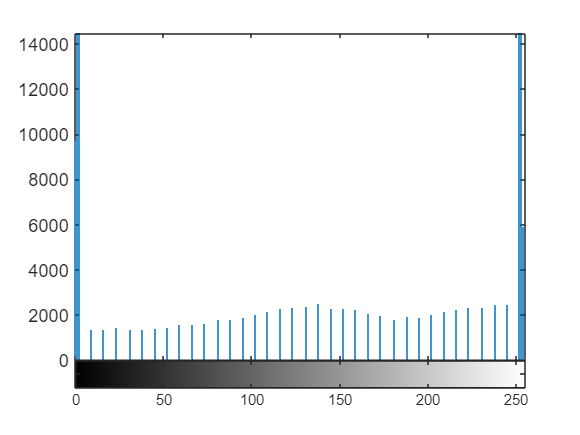

figure
imhist(f)

function c = contraststretching(pippo,a,va,b,vb)
pippo = double(pippo)./255; %normalize the data
% change filter
alpha = va/a; 
beta = (vb - va)/(b-a);
gamma = (1-vb)/(1-b);
I1 = find(pippo <a);
I2 = find(pippo>= a & pippo<= b);
I3 = find(pippo>b);

c(I1) = pippo(I1).*alpha;
c(I2) = ((pippo(I2)-a)).*beta +va;
c(I3) = ((pippo(I3)-b)).*gamma +vb;
size(c);
c = uint8(floor(c.*255));
[N,M] = size(pippo);
c = buffer(c,N);
end

function c2 = contraststretching2(pippo2,a,va,b,vb)
pippo2 = double(pippo2)./255; %normalize the data
% change filter
alpha = va/a; 
beta = (vb - va)/(b-a);
gamma = (1-vb)/(1-b);
I1 = find(pippo2 <a);
I2 = find(pippo2>= a & pippo2<= b);
I3 = find(pippo2>b);

c2(I1) = pippo2(I1).*alpha;
c2(I2) = ((pippo2(I2)-a)).*beta +va;
c2(I3) = ((pippo2(I3)-b)).*gamma +vb;
size(c2);
c2 = uint8(floor(c2.*255));
[N,M] = size(pippo2);
c2 = buffer(c2,N);
end
